## Parameters and Lists

%Generate our Bell Parameter off the correlations:
%Lists:
phi = 0:pi/180:pi;
slist = 0.*phi;

%Parameters:
cycles = 1E4; % C = number of test cycles simulated each time.
loss_rate = 100; % R = retention rate, or quantum efficiency.
dark_rate = 1E-3; % D = dark rate
blur = 0.05; % B = decay width of gaussian blur.
lambda = 0.1; % L = mode occupancy.
R = 1;
phi = pi/4;

colist_test = coordinatelist(4,pi/4,10,cycles,loss_rate,dark_rate,blur,1);

%Evaluation for each phase:
colist_test = coordinatelist(lambda,phi,10,cycles,loss_rate,dark_rate,blur,R);
dlist = [];
total_pairs = 0;
FYZ = 0; FXW = 0; FYW = 0; FXZ = 0;
for i = 1:cycles
    n = size(colist_test{i},1);
    no_pairs = (n^2-n)/2;
    total_pairs = total_pairs + no_pairs;
    if size(colist_test{i})==0
        continue
    end
    no_Ys = length(colist_test{i}(colist_test{i}(:,2)>0 & colist_test{i}(:,3)>0));
    no_Xs = length(colist_test{i}(colist_test{i}(:,2)>0 & colist_test{i}(:,3)<0));
    no_Ws = length(colist_test{i}(colist_test{i}(:,2)<0 & colist_test{i}(:,3)>0));
    no_Zs = length(colist_test{i}(colist_test{i}(:,2)<0 & colist_test{i}(:,3)<0));
    
    FYZ = FYZ + no_Ys * no_Zs;
    FXW = FXW + no_Xs * no_Ws;
    
    FYW = FYW + no_Ys * no_Ws;
    FXZ = FXZ + no_Xs * no_Zs;
end
fYZ = FYZ / total_pairs;
fXW = FXW / total_pairs;
fYW = FYW / total_pairs;
fXZ = FXZ / total_pairs;


colist2 = [];
for i = 1:cycles
    colist2 = [colist2; colist_test{i}];
end
n = size(colist_test{i},1);
no_pairs = (n^2-n)/2;
no_Ys = length(colist2(colist2(:,2)>0 & colist2(:,3)>0));
no_Xs = length(colist2(colist2(:,2)>0 & colist2(:,3)<0));
no_Ws = length(colist2(colist2(:,2)<0 & colist2(:,3)>0));
no_Zs = length(colist2(colist2(:,2)<0 & colist2(:,3)<0));

SYZ = no_Ys * no_Zs;
SXW = no_Xs * no_Ws;
SYW = no_Ys * no_Ws;
SXZ = no_Xs * no_Zs;

sYZ = SYZ / total_pairs;
sXW = SXW / total_pairs;
sYW = SYW / total_pairs;
sXZ = SXZ / total_pairs;

gYZ = fYZ/sYZ;
gXW = fXW/sXW;
gYW = fYW/sYW;
gWZ = fXZ/sXZ;

cycles = 1E5;
QE = 8;
dark_rate = 1E-6; 
blur = 0.05;
R = 1;
lambda = 0.2;
Tmax = 9;
phi = 0;

bias = 0:0.05:1;

gYX = zeros(length(bias),length(bias));
gWZ = zeros(length(bias),length(bias));
gYZ = zeros(length(bias),length(bias));
gXW = zeros(length(bias),length(bias));

for o = 1:length(bias)
    for u = 1:length(bias)
        [gYX(o,u),gWZ(o,u),gYZ(o,u),gXW(o,u)] = correlators(lambda,phi,Tmax,cycles,QE,dark_rate,blur,R,'C',bias(o),bias(u));
        %E_list(p) = (gYX + gWZ - gYZ -  gXW)/(gYX + gWZ + gYZ + gXW);
    end
    percent = 100*o/length(bias)
end

subplot(2,2,1)
surf(bias,bias,gYX)
title("gYX")
subplot(2,2,2)
surf(bias,bias,gWZ)
title("gWZ")
subplot(2,2,3)
surf(bias,bias,gYZ)
title("gYZ")
subplot(2,2,4)
surf(bias,bias,gXW)
title("gXW")

list = coordinatelist(0.9,0,10,1E4,100,0,0.01,1,'Q',0,0)
list2 = [];
for i =1:1E4
    list2 = [list2; list{i}];
end

list3 = list{5};

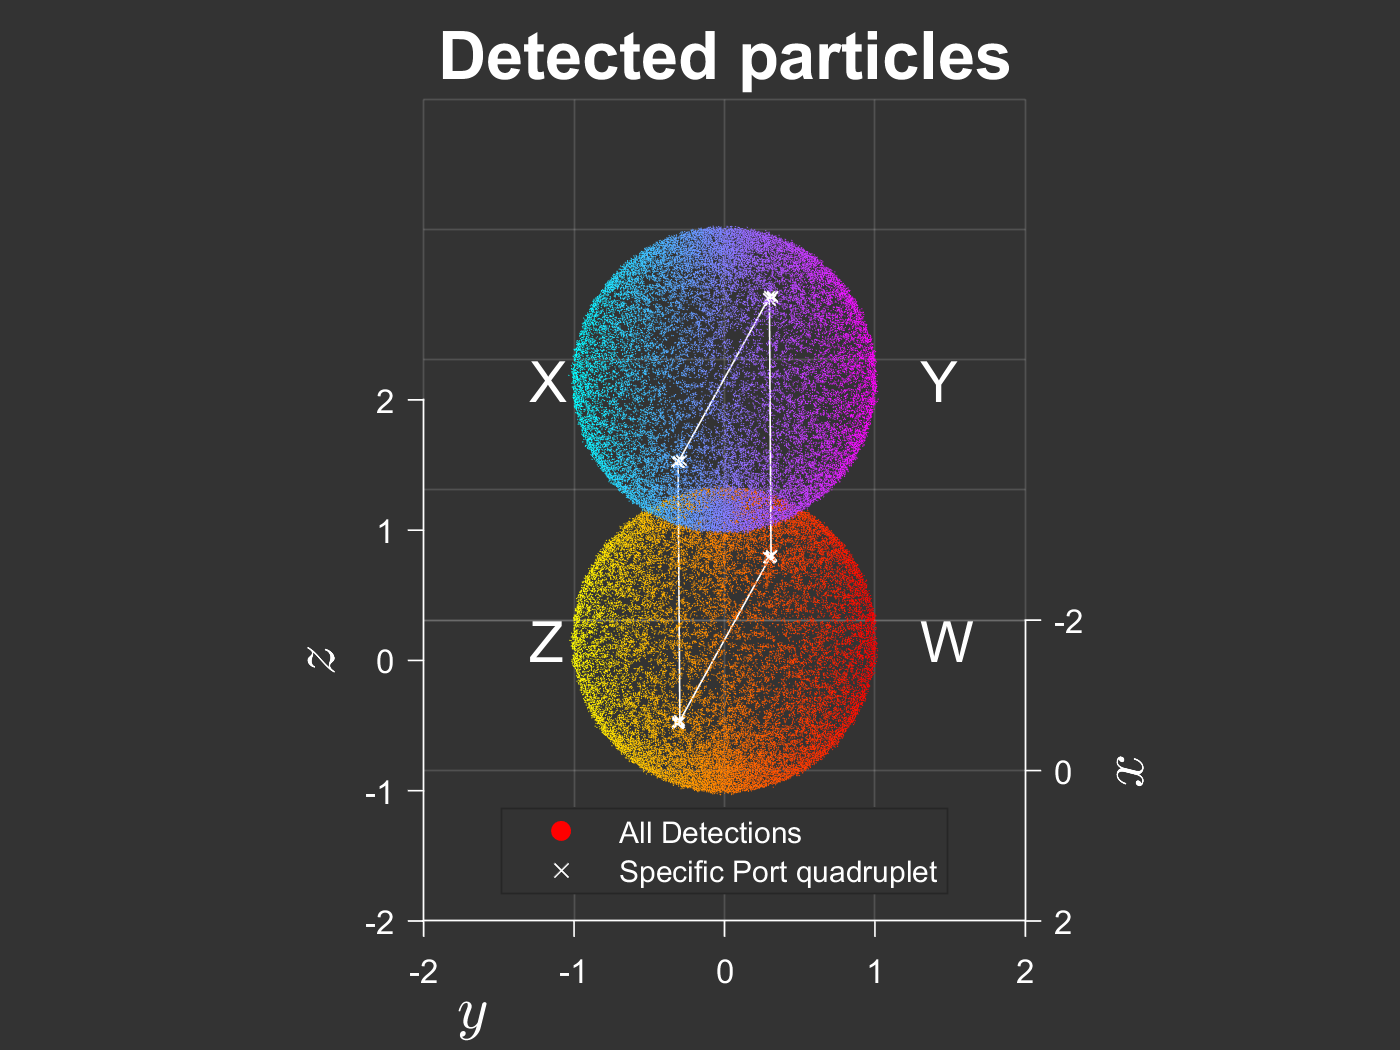

h= figure;
h.Color = [.2 .2 .2];
ax = axes;
ax.Color = [.2 .2 .2];
ax.XColor = [1 1 1];
ax.YColor = [1 1 1];
ax.ZColor = [1 1 1];
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.ZGrid = 'on';
ax.GridColor = [1 1 1];

x = list2(:,1);
y = list2(:,2);
z = list2(:,3);
cmap = [autumn(32); cool(32)];
colormap(cmap)

hold on
axes(ax)
scatter3(x,y,z,0.2,(y+1.05).*z./(abs(z)),'filled')
scatter3(list3(:,1),list3(:,2),list3(:,3),20,'wx')
plot3([list3(1,1) list3(6,1)],[list3(1,2) list3(6,2)],[list3(1,3) list3(6,3)],'white')
plot3([list3(1,1) list3(11,1)],[list3(1,2) list3(11,2)],[list3(1,3) list3(11,3)],'white')
plot3([list3(16,1) list3(11,1)],[list3(16,2) list3(11,2)],[list3(16,3) list3(11,3)],'white')
plot3([list3(16,1) list3(6,1)],[list3(16,2) list3(6,2)],[list3(16,3) list3(6,3)],'white')

hold off
xlim([-2 2])
ylim([-2 2])
zlim([-2 2])
view(90,30)
title("Detected particles",'Color','w','FontSize',20)
xlabel("$x$",'FontSize',18,'Interpreter','latex')
ylabel("$y$",'FontSize',18,'Interpreter','latex')
zlabel("$z$",'FontSize',18,'Interpreter','latex')
daspect([1 1 1])
text(0,1.3,1,'Y','Color','w','FontSize',17)
text(0,-1.3,1,'X','Color','w','FontSize',17)
text(0,1.3,-1,'W','Color','w','FontSize',17)
text(0,-1.3,-1,'Z','Color','w','FontSize',17)
l = legend("All Detections","Specific Port quadruplet");
l.Location = 'south';
l.TextColor = 'w';

set(gca,'nextplot','replacechildren');
loops = 810;
M(loops) = struct('cdata',[],'colormap',[]);
%h.Visible = 'off'
v = VideoWriter('dark_detections.avi');
v.FrameRate = 12;
open(v);
for j = 1:loops
    view(j,15*(cos(2*pi*j/loops)+1))
    drawnow
    M(j) = getframe(gcf);
    writeVideo(v,M(j));
end

close(v);

view(90,20)

colormapeditor